Load robot model, set joint angles for home position

clear all;
clc; 
%close all;

% Specify Dh parameters
dhparams = [
    %a(t_x)   alpha(r_x)   d(t_z)    theta(r_z) 
    0.000     -pi/2         0.000     0.000;      % Fixed world
    0.000     -pi/2        10.000    0.000;      % prismatic joint simulating mobile base
    0.000     pi/2         0.109     0.000;      % shoulder yaw 
    0      -pi/2        0.15     0.000;        % shoulder pitch
    0.00     0        0.1     0;            %shoulder prismatic
    0      -pi/2        0.4    0.0;         %first roll joint
    0      pi/2        0.2     0           %first pitch
    0      -pi/2       0.4     0         %roll 2
    0      pi/2        0.2     0        %pitch2
    0      0           0.4     0        %roll 3
    ];

% Define the joint types

rev = "revolute";
pris = "prismatic";
fix = "fixed";
jointTypes = [fix, pris, rev, rev, pris, rev, rev, rev, rev, rev];
q_home = [0, 0, 0, 0, 0, 0, 0, 0, 0];

% Call function to create rigid body tree model

robot = createRobotModel_Generalized(dhparams, jointTypes, q_home)

robot =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'body1'  'body2'  'body3'  'body4'  'body5'  'body6'  'body7'  'body8'  'body9'  'body10'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'row'


showdetails(robot);

--------------------
Robot: (10 bodies)

 Idx     Body Name   Joint Name   Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------   ----------   ----------     ----------------   ----------------
   1         body1         jnt1        fixed              base(0)   body2(2)  
   2         body2         jnt2    prismatic             body1(1)   body3(3)  
   3         body3         jnt3     revolute             body2(2)   body4(4)  
   4         body4         jnt4     revolute             body3(3)   body5(5)  
   5         body5         jnt5    prismatic             body4(4)   body6(6)  
   6         body6         jnt6     revolute             body5(5)   body7(7)  
   7         body7         jnt7     revolute             body6(6)   body8(8)  
   8         body8         jnt8     revolute             body7(7)   body9(9)  
   9         body9         jnt9     revolute             body8(8)   body10(10)  
  10        body10        jnt10     revolute             body9(9)   
-------

robot.getBody("body2").Joint.PositionLimits = [0, 10];
robot.getBody("body5").Joint.PositionLimits = [0.3, 0.73];


% Check for collisions in home configuration
% 
% [isColliding, sepDist, witnessPts] = checkCollision(robot, q_home);
% 
% if isColliding
%     disp('The robot is in self-collision in the home configuration.');
% else
%     disp('No self-collision detected in the home configuration.');
% end

Set joint limits and show arm in home position

config = homeConfiguration(robot);
eeName = robot.BodyNames{end};

gui = interactiveRigidBodyTree(robot,"Configuration",config)

gui =   interactiveRigidBodyTree with properties:

           RigidBodyTree: [1×1 rigidBodyTree]
                IKSolver: [1×1 generalizedInverseKinematics]
       SolverPoseWeights: [1 1]
             Constraints: {}
          MarkerBodyName: 'body10'
     MarkerControlMethod: 'InverseKinematics'
       MarkerScaleFactor: 1
              ShowMarker: 1
           Configuration: [9×1 double]
    StoredConfigurations: []
              MarkerPose: [4×4 double]
          MarkerBodyPose: [4×4 double]


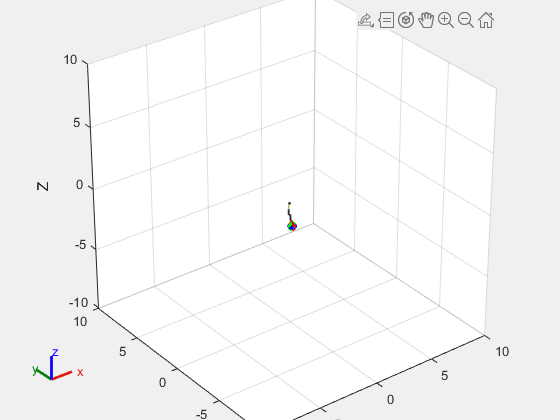

% figure;
% show(robot,q_home, Visuals="off", Collisions="on");
axis equal;          
xlim([-10, 10]);   
ylim([-10, 10]);      
zlim([-10, 10]);   
view(3);   
hold on

Generate environment

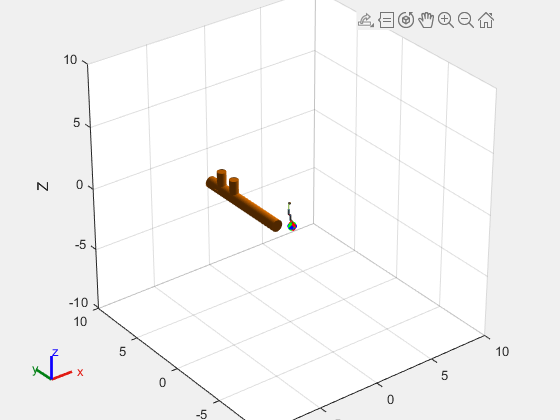

collisionCylinders = {
    collisionCylinder(0.457, 8.0),  % Main Pipe
    collisionCylinder(0.044, 0.3),  % Front BLM
    collisionCylinder(0.044, 0.3),  % Back BLM
    collisionCylinder(0.350, 1.5),  % First Obstacle
    collisionCylinder(0.350, 1.5)   % Second Obstacle
};

cylinderPoses = [
    -0.958, 4.260, -1.707, 1, 0, 0, pi/2; 
    -0.458, 2.015, -1.627, 1, 0, 0, pi/2;
    -1.456, 6.921, -1.627, 1, 0, 0, pi/2; 
    -0.952, 5.400, -0.986, 1, 0, 0, 0;
    -0.952, 6.900, -0.986, 1, 0, 0, 0
];

for i = 1:length(collisionCylinders)
    P = trvec2tform(cylinderPoses(i, 1:3));
    R = axang2tform(cylinderPoses(i, 4:7));
    collisionCylinders{i}.Pose = P * R;
    show(collisionCylinders{i});
end

Define goal poses

goalPoses = [
          -0.000, 1.700, 0.500, 0, 1, 0, pi/2;  % Start
          -0.476, 2.015, -1.400, 0, 1, 0, pi/2;  % Front BLM
            ];

disp('Plotting all target poses...');

Plotting all target poses...


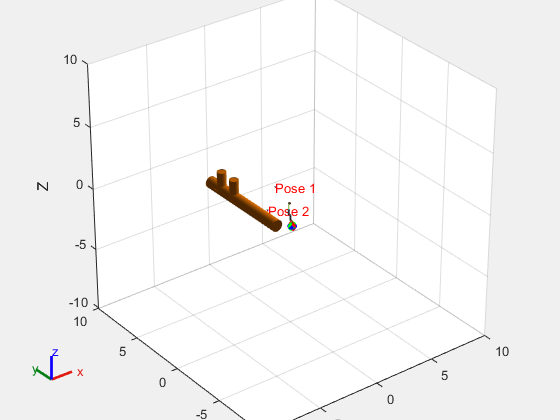

for i = 1:size(goalPoses, 1)
    pos = goalPoses(i, 1:3);
    rot = goalPoses(i, 4:7);
    poseTF = trvec2tform(pos) * axang2tform(rot);
    
    plotTransforms(pos, tform2quat(poseTF), "FrameSize", 0.1);
    text(pos(1), pos(2), pos(3), sprintf('Pose %d', i), 'FontSize', 10, 'Color', 'r');
end

Create RRT trajectory planner

planner = manipulatorRRT(robot,collisionCylinders);
planner.SkippedSelfCollisions = 'parent';
planner.EnableConnectHeuristic = true

planner =   manipulatorRRT with properties:

      MaxConnectionDistance: 0.1000
              MaxIterations: 10000
     EnableConnectHeuristic: 1
         ValidationDistance: 0.0100
    WorkspaceGoalRegionBias: 0.5000
        IgnoreSelfCollision: 0
      SkippedSelfCollisions: 'parent'


planner.MaxConnectionDistance = 0.1;
planner.ValidationDistance = 0.01;
planner.MaxIterations = 100;

Create IK solver

Press Enter to move to the next pose...


Pose 1 error vector: [-0.0000, -0.0000, -0.0000, -0.6416, 0.1405, -0.0000]


Press Enter to move to the next pose...


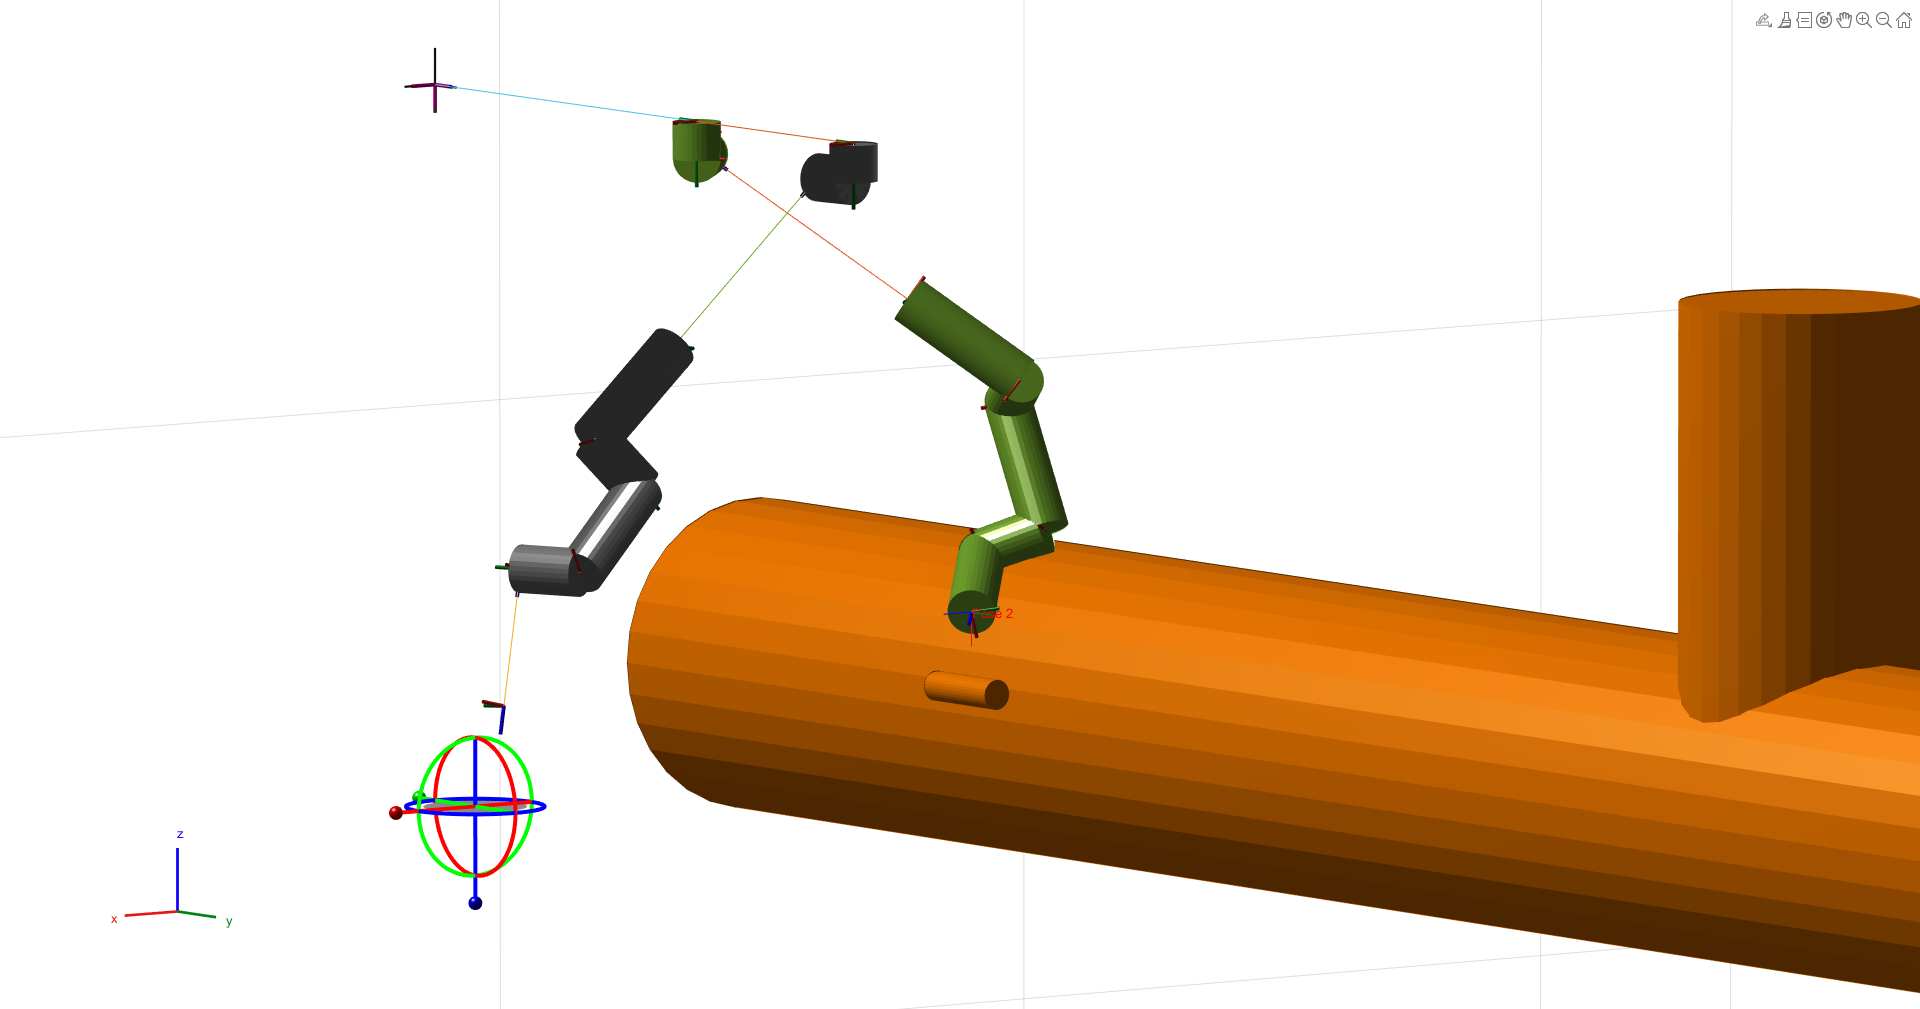

Pose 2 error vector: [-0.0000, 0.0000, -0.0000, 0.8244, -0.3798, 0.0000]


ik = inverseKinematics('RigidBodyTree', robot);
ikWeights = [1 0 0 1 1 1]; % [orientation weights, then position weights]
qInitial = config;

numGoals = size(goalPoses, 1);
qSolutions = zeros(numel(config), numGoals);
errorVectors = zeros(6, numGoals);  % to store 6-element error vectors

for i = 1:numGoals
    % Wait for user input before proceeding to the next pose.
    disp('Press Enter to move to the next pose...');
    pause;
    
    % Extract desired pose (translation and axis-angle rotation)
    pos = goalPoses(i, 1:3);
    axang = goalPoses(i, 4:7);
    targetTform = trvec2tform(pos) * axang2tform(axang);
    
    % Compute IK solution from current qInitial.
    [qSol, solInfo] = ik(eeName, targetTform, ikWeights, qInitial);
    qSolutions(:, i) = qSol(:);
    
    % Generate an interpolated trajectory from qInitial to qSol:
    numInterpSteps = 50;  % adjust for smoothness
    jointWaypoints = [qInitial(:), qSol(:)];  % each column is a configuration
    q_traj = trapveltraj(jointWaypoints, numInterpSteps);
    
    % Animate the trajectory.
    for k = 1:numInterpSteps
        qCurrent = q_traj(:, k);
        show(robot, qCurrent', 'PreservePlot', false, 'Visuals','off','Collisions','on');
        title(sprintf('Moving from Pose %d to Pose %d, step %d/%d', i, i, k, numInterpSteps));
        drawnow;
        pause(0.02);  % adjust for desired animation speed
    end
    
    % After finishing the trajectory, compute the error vector at final pose.
    T_actual = getTransform(robot, qSol, eeName);
    posDesired = tform2trvec(targetTform);
    posActual  = tform2trvec(T_actual);
    posErrorVector = posDesired - posActual;  % [ex, ey, ez]
    
    % Orientation error:
    R_desired = tform2rotm(targetTform);
    R_actual  = tform2rotm(T_actual);
    R_err = R_actual' * R_desired;  % relative rotation: R_actual * R_err = R_desired
    axang_err = tform2axang([R_err, zeros(3,1); 0 0 0 1]);
    orientErrorVector = axang_err(1:3) * axang_err(4);  % [erx, ery, erz]
    
    errorVector = [posErrorVector, orientErrorVector];
    errorVectors(:, i) = errorVector;
    
    fprintf('Pose %d error vector: [%.4f, %.4f, %.4f, %.4f, %.4f, %.4f]\n', ...
        i, errorVector(1), errorVector(2), errorVector(3), ...
        errorVector(4), errorVector(5), errorVector(6));
    
    % Update initial configuration for the next pose.
    qInitial = qSol;
end